# Figure 12

## load data

whichData = 'fmri1'; 
dataLoc      = fullfile(temporalfMRIRootPath, 'files');

[a, b]    = loadfiles(dataLoc, whichData);
roiNms    = a.(whichData).nm;
nRois     = length(roiNms);

roiNms = a.fmri1.nm;

% load models
stn = {};
stn{1} = b.fmri1.stn;
stn{2} = b.fmri1.stn_var1;
stn{3} = b.fmri1.stn_var2;

lin = b.fmri1.lin;

## average model parameters

% average model parameters
mparam = {};
sparam = {};

for k = 1: 3
    for iroi = 1 : nRois
        idx = (iroi - 1) * 100 + 1 : iroi * 100;
        mparam{k}(iroi, :)    = median(stn{k}.param(idx, :));
        sparam{k}(iroi, :, :) = prctile(stn{k}.param(idx, :), [25, 75]);
        
        % average summary metrics
        m_smetrics{k}(iroi, 1) = median(stn{k}.derivedParam.r_double(idx));
        s_smetrics{k}(iroi, 1, :) = prctile(stn{k}.derivedParam.r_double(idx), [25, 75]);
        
        m_smetrics{k}(iroi, 2) = median(stn{k}.derivedParam.t_isi(idx));
        s_smetrics{k}(iroi, 2, :) = prctile(stn{k}.derivedParam.t_isi(idx), [25, 75]);
        
        % average xr2
        m_xr2{k}(iroi)    = median(stn{k}.xr2(idx));
        s_xr2{k}(iroi, :) = prctile(stn{k}.xr2(idx), [25, 75]);
        m_linxr2(iroi)    = median(lin.xr2(idx));
    end
end


## plot figure 12

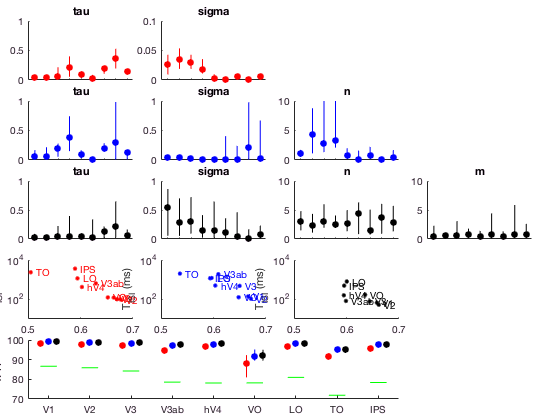

figure (12), clf, 

% plot model parameters
markerColor = {'r', 'b', 'k'}; param_label = {'tau', 'sigma', 'n', 'm'};
for k = 1 : 3
   for k1 = 1 : size(mparam{k}, 2) -1
      subplot_tight(5, 4, (k - 1) * 4 + k1, 0.05), 
      plot(mparam{k}(:, k1), 'o', 'markerfacecolor', markerColor{k}, 'markeredgecolor', markerColor{k}), hold on
      for k2 = 1 : nRois
         plot([k2, k2], [sparam{k}(k2, 1, k1), sparam{k}(k2, 2, k1)], '-', 'color', markerColor{k}) 
      end
      set(gca, 'xtick', 1 : 9, 'xticklabel', ''), xlim([0.4, nRois + 0.5]), title(param_label{k1})
      box off
   end
end

% plot summary metrics
for k = 1 : 3
    subplot_tight(5, 4, 12 + k, 0.05),
    semilogy(m_smetrics{k}(:, 1), m_smetrics{k}(:, 2), '.', 'color', markerColor{k}, 'markersize', 12),
    text(m_smetrics{k}(:, 1)+0.01, m_smetrics{k}(:, 2), roiNms, 'color', markerColor{k})
    xlim([0.5, 0.7]), ylim([10, 10^4]), box off, xlabel('R_{double}'), ylabel('T_{ISI} (ms)')
end

% plot xr2
subplot_tight(5, 4, 17 : 19, 0.05), cla,  shift = [-0.2, 0, 0.2];
for k = 1 : 3
    plot([1 : nRois]+shift(k), m_xr2{k}, 'o', 'markerfacecolor', markerColor{k}, 'markeredgecolor', markerColor{k}), hold on
    for iroi = 1 : nRois
        plot([iroi+shift(k), iroi + shift(k)], s_xr2{k}(iroi, :), '-', 'color', markerColor{k})
    end
end
% plot linear x-r2:
for iroi = 1 : nRois
   plot([iroi - 0.2, iroi + 0.2], [m_linxr2(iroi), m_linxr2(iroi)], 'g-') 
end
box off, xlim([0.5, nRois + 0.5]), set(gca, 'xticklabel', roiNms), ylabel('x-R^2'), ylim([70, 100])